# **Элементы программирования**

## Теория

### 3.1.1 Специальные символы

pi; % число пи
ans; % результат выполнения операции
inf; % бесконечность
nan; % нечисловое значение

#### Пример 1

1e309
1 / inf 
inf - inf
inf + nan
1 / nan
1 / 0
-1 / 0
0 / 0

### 3.1.2 Типы данных

help DataTypes

Функции определения типа данных:

% isinf, isfinite, isnan, isnumeric, islogical, ischar, iscell, isstruct,
% isfloat, isinteger, isobject, isjava, issparse, isreal, class, isa

### 3.1.3 Текстовые строки

s3 = 'Hello, Matlab'
disp(s3)
n1 = input('Input the num ')
help strfun

### 3.2 Управление вычислением

#### Пример 2

% Определить знак S рационального числа X

X = 20
% if: оператор условия: вычисляет логическое выражение и выполняет группу операторов, если выражение истинно

if X > 0
    S = 1;
elseif ~X % все ненулевые значения будут нулями, нуль - единицей
    S = 0;
else
    S = -1;
end

S

% Вариант 2 (без оператора if):

X = [4:-2:-4], S = (X > 0) - (X < 0)

#### Пример 3

% switch: оператор переключения: выполняет группу операторов в зависимости от значения переменной или выражения

appl = 'MATLAB';
switch upper(appl)
    case {'MATLAB', 'MATCAD'}
        disp('Application is numeric')
    case {'MAPLE', 'MATHEMATICA'}
        disp('Application is symbolic')
    otherwise
        disp('Unknown application')
end

#### Пример 4

n = 7;
switch n
 case {1, 4, 9}, fprintf('%d – Quadrate\n', n);
 case {2, 3, 5, 7}, fprintf('%d – Prima\n', n);
 case 6, fprintf('%d – factorial 3!\n', n);
 case 8, fprintf('%d – Cubic\n', n);
 otherwise
 disp('n must be natural number from 1 to 9.');
end

% Вычислить сумму отрезка ряда с заданной точностью

S = 0; n = 1; x = 1;
while x > 1e-10
    S = S + x;
    n = n + 1; x = 1 / factorial(n);
end
[x, n]
% while: оператор цикла: повторяет группу операторов до тех пор, пока выполняется логическое условие;
% for: оператор цикла: выполняет группу операторов заданное число раз;
% break: оператор управления: выполняет досрочный выход из циклов for или while;
% continue: оператор управления: передает управление следующей итерации циклов for или while. 

## Задания

### Задание 1

Чему равно наибольшее число, для которого можно вычислить факториал в пакете MATLAB?

n = 1;
while ~isinf(factorial(n))
    n = n + 1;
end

disp(n)
fprintf('%d! = %d, %d! = %d', n - 1, factorial(n - 1), n, factorial(n));

% другой вариант

n = 1;
while true
    if factorial(n) == inf
        n = n - 1;
        break;
    else
        n = n + 1;
    end
end

disp(n)

### Задание 2

Организуйте цикл, в котором вводите с клавиатуры название дня недели, и при помощи оператора switch определите номер дня недели по названию дня недели. Выход из цикла – по вводу текстовой строки «exit». Обработайте некорректный ввод названия дня недели.

exit = false
while ~exit
    day = input('Enter the day of the week: ', 's')
    switch upper(day)
    case 'MONDAY'
        day_n = 1;
    case 'TUESDAY'
        day_n = 2;
    case 'WEDNESDAY'
        day_n = 3;
    case 'THURSDAY'
        day_n = 4;
    case 'FRIDAY'
        day_n = 5;
    case 'SATURDAY'
        day_n = 6;
    case 'SUNDAY'
        day_n = 7;
    case 'EXIT'
        exit = true;
    otherwise
        day_n = 0;
    end
    if exit
        disp('The exit.')
    elseif ~day_n
        disp('Incorrect input. Try again.')
    else
        disp(['The num of the ', day, ' is ', int2str(day_n), '.'])
    end
end

### Задание 3

Организуйте цикл, в котором вводите с клавиатуры номер месяца, и при помощи оператора switch определите название месяца по его номеру. Обработайте некорректный ввод номера дня недели. Выход из цикла – по вводу числа 0.

exit = false
while ~exit
    month_n = input('Enter the month of the year: ', 's')
    switch month_n
    case '1'
        month = 'January';
    case '2'
        month = 'February';
    case '3'
        month = 'March';
    case '4'
        month = 'April';
    case '5'
        month = 'May';
    case '6'
        month = 'June';
    case '7'
        month = 'July';
    case '8'
        month = 'August';
    case '9'
        month = 'September';
    case '10'
        month = 'October';
    case '11'
        month = 'November';
    case '12'
        month = 'December';
    case '0'
        exit = true;
    otherwise
        month = 0;
    end
    if exit
        disp('The exit.')
    elseif ~month
        disp('Incorrect input. Try again.')
    else
        disp(['The ', month_n, ' month of the year is ', month, '.'])
    end
end

### Задание 4

Функция input. Введите и выполните команды.

M = input('Input (nx2)-Matrix: ')

### Задание 5

Функция input и disp. Введите и выполните команды.

A = input('Input the Number : A = ')

disp(['The number A is: ', int2str(A)])

S = input('Input the string : S = ', 's')

### Задание 6

3D-графика. Введите команды.

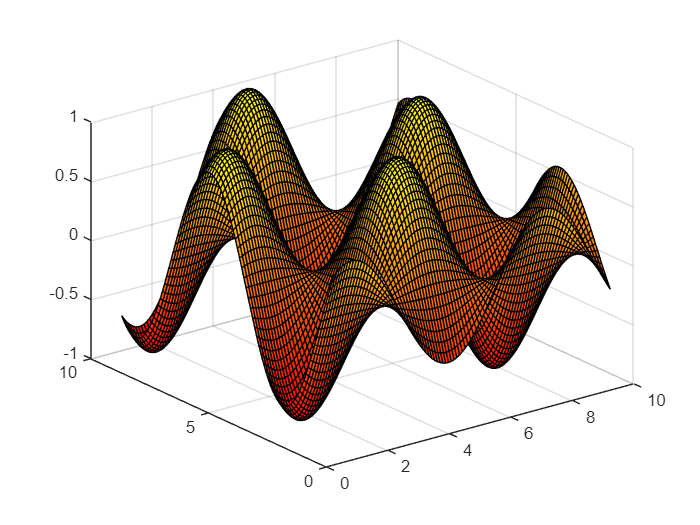

a = linspace(1, 10, 100);
[x y] = meshgrid(a); % возвращает 2D сетку координат, основанную на координатах, содержащихся в векторе a, x - матрица, где каждая строка копия a y - это матрица,
% где каждый столбец - копия a
z = sin(x) .* cos(y);
surf(x, y, z)

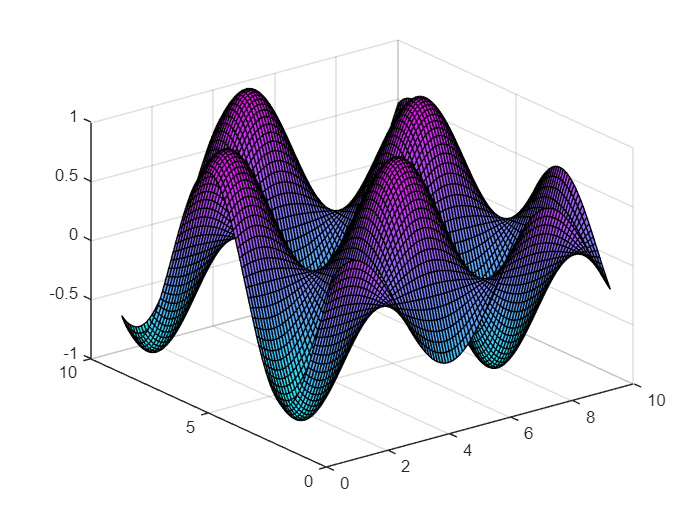

colormap cool

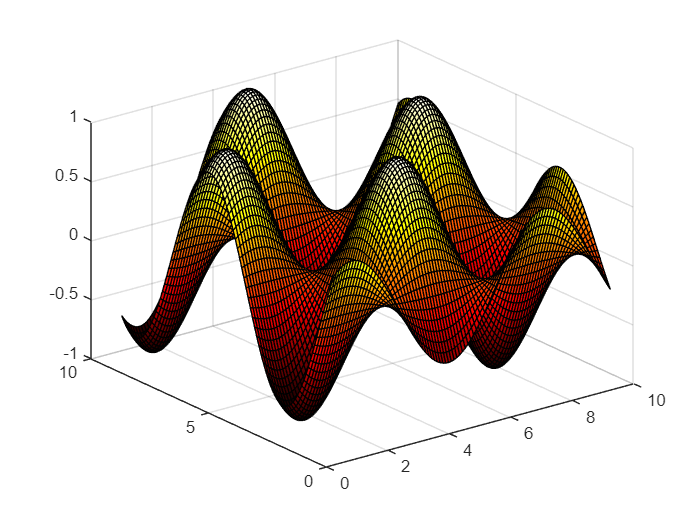

colormap hot

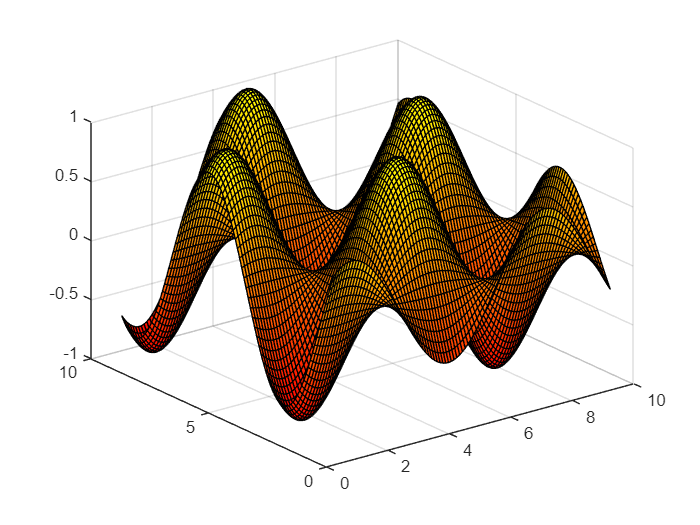

colormap autumn

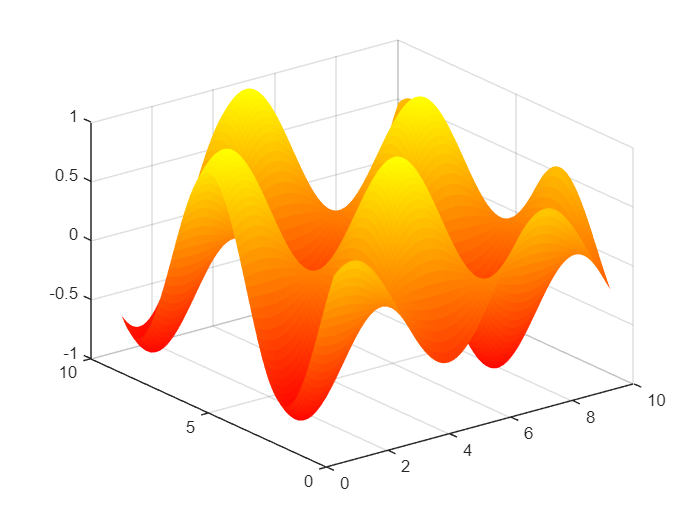

shading flat

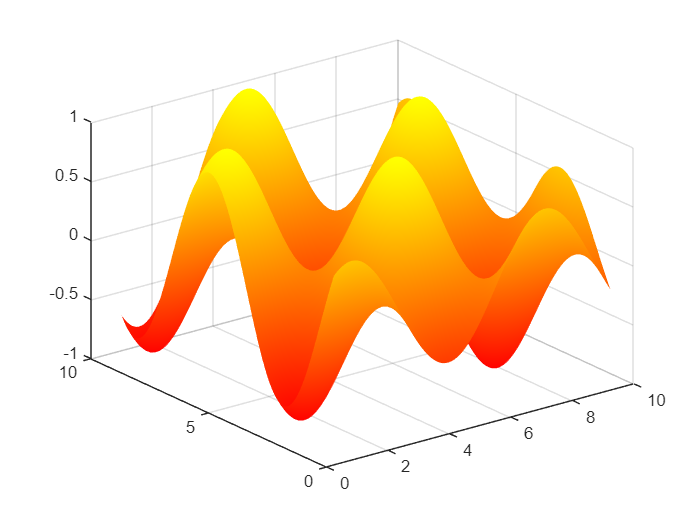

shading interp

shading faceted